# Q1 Download the wine data set from the UCI database.  Train a network with 2 hidden units on the data, holding out 10 items from each category for testing.

% set up
clear;
rs = 0

rs =      0

% obtain data
wine = str2num(urlread("https://archive.ics.uci.edu/ml/machine-learning-databases/wine/wine.data"));

% turn 1,2,3 output to [1 0 0], [0 1 0], [0 0 1]
data = [dummyvar(categorical(wine(:,1))) wine(:,2:end)];

% Correction: use build-in wine_dataset
[s,t] = wine_dataset;
data = [t' s']

data =             1            0            0        14.23         1.71         2.43         15.6          127          2.8         3.06         0.28         2.29         5.64         1.04         3.92         1065
            1            0            0         13.2         1.78         2.14         11.2          100         2.65         2.76         0.26         1.28         4.38         1.05          3.4         1050
            1            0            0        13.16         2.36         2.67         18.6          101          2.8         3.24          0.3         2.81         5.68         1.03         3.17         1185
            1            0            0        14.37         1.95          2.5         16.8          113         3.85         3.49         0.24         2.18          7.8         0.86         3.45         1480
            1            0            0        13.24         2.59         2.87           21          118          2.8         2.69         0.39         1.82 

% Correction: using zscore on data for better learning
data = [data(:,1:3) zscore(data(:,4:end))]

data =             1            0            0       1.5143     -0.56067       0.2314      -1.1663       1.9085      0.80672       1.0319     -0.65771       1.2214      0.25101      0.36116       1.8427       1.0102
            1            0            0       0.2456     -0.49801     -0.82567      -2.4838     0.018094      0.56705      0.73157     -0.81841     -0.54319      -0.2925      0.40491       1.1103      0.96253
            1            0            0      0.19633     0.021172       1.1062     -0.26798      0.08811      0.80672       1.2121     -0.49701         2.13      0.26826      0.31741      0.78637       1.3912
            1            0            0       1.6868     -0.34584      0.48655     -0.80697       0.9283       2.4844       1.4624     -0.97911       1.0293       1.1827     -0.42634       1.1807        2.328
            1            0            0      0.29487      0.22705       1.8352      0.45067       1.2784      0.80672      0.66149      0.22616      0.40028 

% Correction End

% catalog data to test_set(10), and training_set(whatever left)
test_set = [];
valid_set = []; 
for i = 1:3 % for each category
    cat_wine = data(data(:, i) > 0, :);
    % Randomly select unrepeatable 10 item for testing
    indexes = randperm(size(cat_wine, 1), 20)
    test_set = [test_set; cat_wine(indexes(:,1:10), :)];
    % Correction: no need to pick vilidation set, see Q1.a for detail
    valid_set = [valid_set; cat_wine(indexes(:,11:20), :)];
end

indexes =     45    46    40     5     3    42    18    25    39    27    26     6    11    12    20    53     7    13    55    38


indexes =     53    22    28    24    54    34    39    26    68    11     7    66    43    32    18    17    25    59    38    15


indexes =     41    31     6    18     3    30    40    36    38    15    27    29     2    19    42    22    37    46    34    43


% training = original - test
train_set = setdiff(data, [test_set; valid_set], "rows");
isequal(sortrows(data),sortrows([train_set;valid_set;test_set])) % sanity check

ans = logical
   1


% reshape data
training.smat = train_set(:,4:end);
training.tmat = train_set(:,1:3);

testing.smat = test_set(:,4:end);
testing.tmat = test_set(:,1:3);

validation.smat = valid_set(:,4:end);
validation.tmat = valid_set(:,1:3);

## a. Show the error curves over time

% init random 1 layer network with stimulus(13) input, 2 hidden, and 3 output
q1net0 = initnet3(13,2,3,1,1,rs)

q1net0 = struct with fields:
      wih: [2×13 double]
    hbias: [0.24313 -0.10777]
    whout: [3×2 double]
    obias: [-0.40287 0.32346 0.19483]

q1net0.wih

ans =       0.31472     -0.37301      0.13236      -0.2215      0.45751     -0.34239      0.45717      0.30028    -0.078239      0.29221      0.15574      0.34913      0.17874
      0.40579      0.41338     -0.40246     0.046882      0.46489      0.47059    -0.014624     -0.35811      0.41574      0.45949     -0.46429      0.43399      0.25774


q1net0.whout

ans =       0.15548     -0.46817
     -0.32881     -0.22308
      0.20605     -0.45383


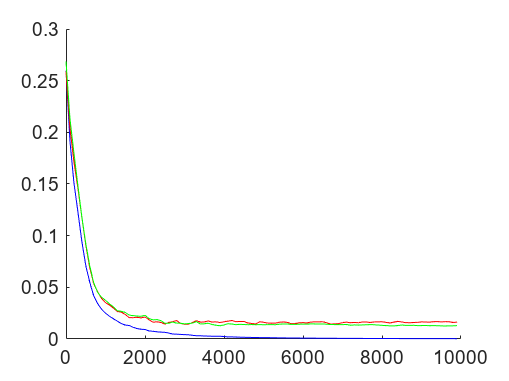


niter = 10000; % n-th iteration
eta = 0.02; % Eta, learning rate
nlev = 0; % noise level
[bestnet,finalnet,errmat] = bp3trvats(q1net0,training,validation,testing,niter,eta,nlev,.01);
% Correction: code a simpler `bp3trvats` function which exclude the
% "validation" part. See attachment `bp3errortrack`


figure
err = errmat(1:niter/100:niter,:);
hold on
plot(err(:,1),err(:,2),'b')
plot(err(:,1),err(:,3),'r')
plot(err(:,1),err(:,4),'g')
hold off


% Correction: add log to plot

## b. Show the final confusion matrix (3 categories)

target = data(:,1:3);
stim = data(:,4:end);
pats.smat = stim;
pats.tmat = target;

bestact=forw3(bestnet, pats)

bestact = struct with fields:
    stim: [178×13 double]
     hid: [178×2 double]
     out: [178×3 double]

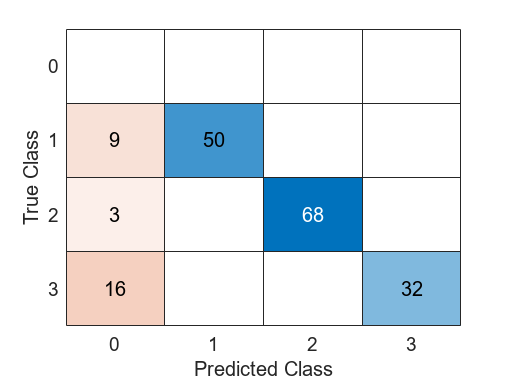

% build confusion matrix
[~,t] = max(target, [], 2);
[~,o] = max(bestact.out,[],2);

% Correction: a less confusing way of doing above
t = target * [1; 2; 3];
o = (bestact.out>0.9) * [1; 2; 3];
% Correction End

figure
confusionchart(t,o)

## c. Plot the hidden unit representations using different colors for the wine type.

act = forw3(bestnet,pats)

act = struct with fields:
    stim: [178×13 double]
     hid: [178×2 double]
     out: [178×3 double]

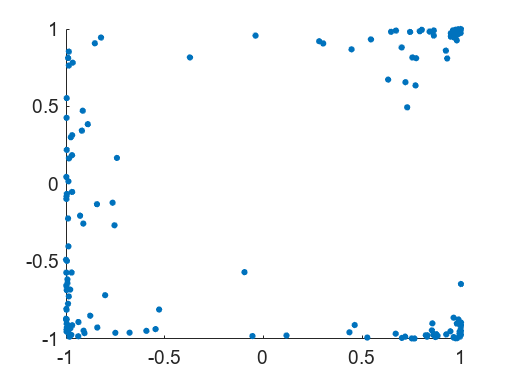

act.hid;
color = [training.tmat,zeros(size(training.tmat)),1-training.tmat];
scatter(act.hid(:,1),act.hid(:,2),10,"filled")

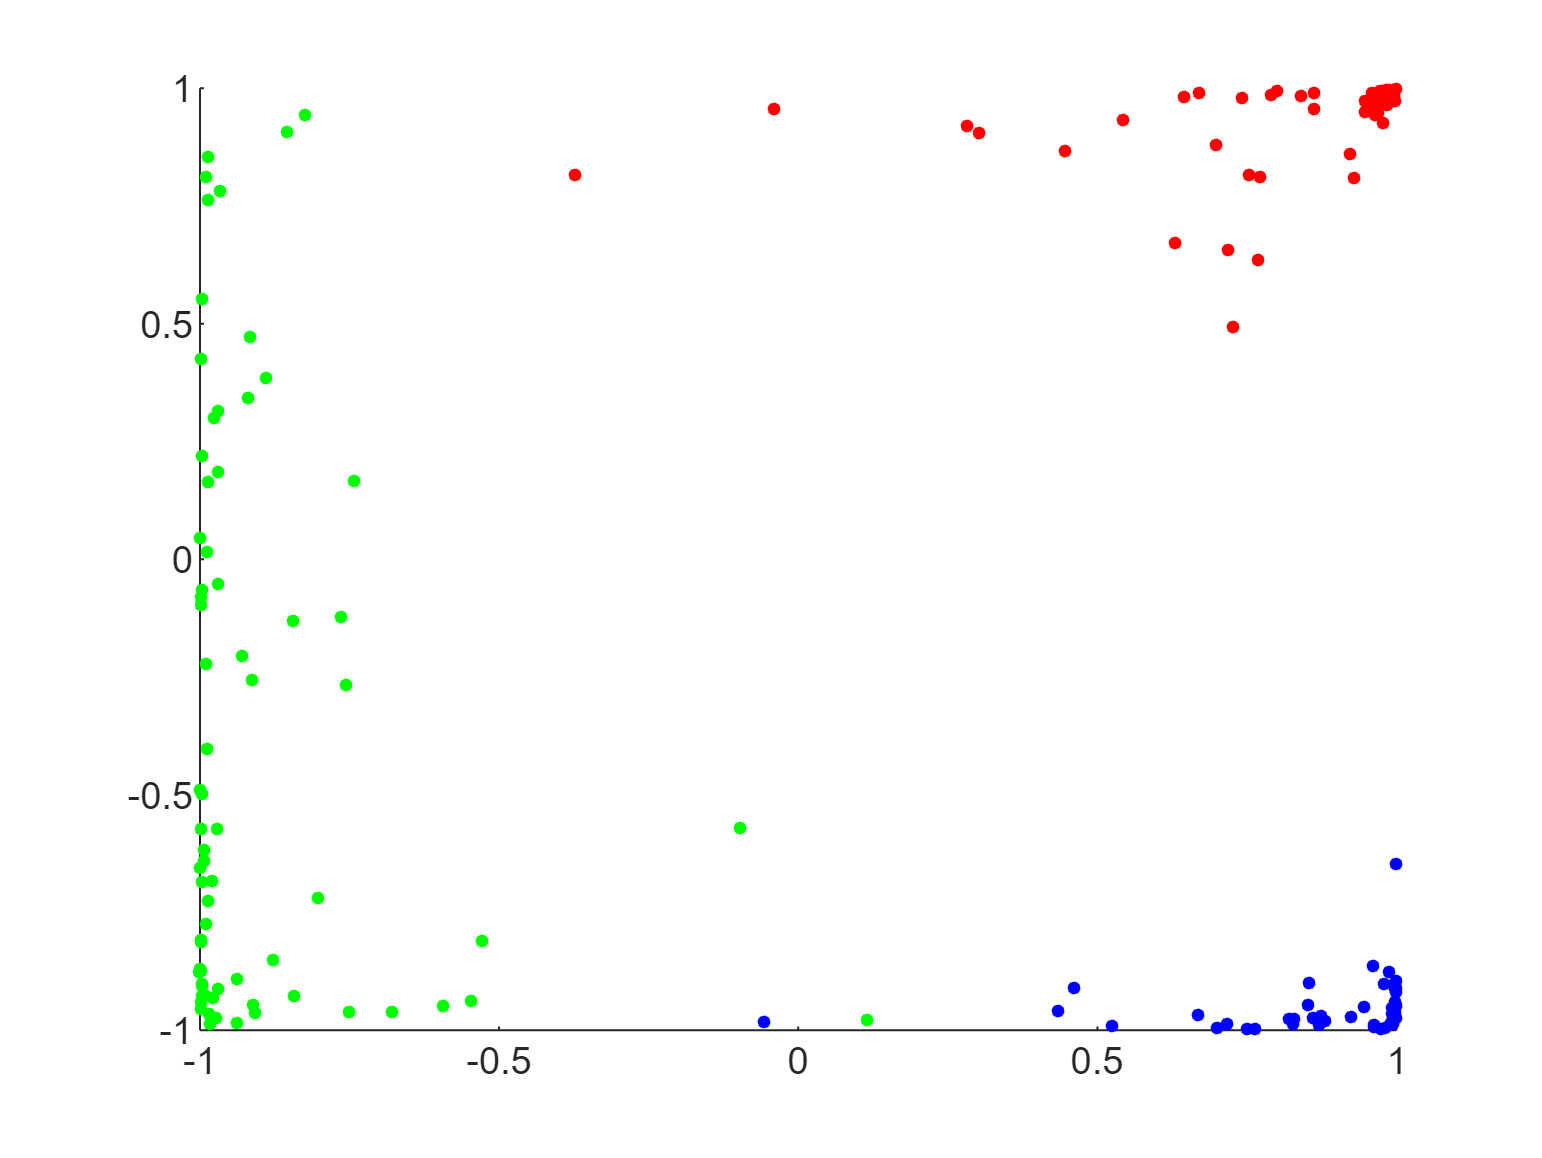


% Correction: set color matrix [r, g, b] as target matrix [1, 2, 3], how coincidentally convinence
figure 
scatter(act.hid(:,1),act.hid(:,2),10,pats.tmat,"filled")

% Correction End

## Q2 The following table summarizes BMI data from 300 patients, of which 100 have been diagnosed with breast cancer.

%{
BMI (kg/m3)   <18 18-20 20-22 22-24 24-26 26-28 28-30 30-32 32-34 34-36 36-38 38-40
Cancer (n=100) 0    1     4    10    19    19    13    13     4    10     6     1
No Cancer	   2   21    60    37    27    26    10     3     8     2     3     1
%}

bmi = [	"<18"	"18-20"	"20-22"	"22-24"	"24-26"	"26-28"	"28-30"	"30-32"	"32-34"	"34-36"	"36-38"	"38-40"];
cancer = [0	1	4	10	19	19	13	13	4	10	6	1];
no_cancer = [2	21	60	37	27	26	10	3	8	2	3	1];

## a. Compute the number of true positives, true negatives, false positives and false negatives at each BMI level.

cdata = [];
b = 18;
for i=1:length(bmi)
    cdata = [cdata; [b sum(cancer(:,i+1:end)) sum(cancer(:,1:i)) sum(no_cancer(:,i+1:end)) sum(no_cancer(:,1:i))]];
    b = b+2;
end
["bmi_cutoff" "tp" "tn" "fp" "fn"; cdata]

ans = 13×5 string array
    "bmi_cutoff"    "tp"     "tn"     "fp"     "fn" 
    "18"            "100"    "0"      "198"    "2"  
    "20"            "99"     "1"      "177"    "23" 
    "22"            "95"     "5"      "117"    "83" 
    "24"            "85"     "15"     "80"     "120"
    "26"            "66"     "34"     "53"     "147"
    "28"            "47"     "53"     "27"     "173"
    "30"            "34"     "66"     "17"     "183"
    "32"            "21"     "79"     "14"     "186"
    "34"            "17"     "83"     "6"      "194"
    "36"            "7"      "93"     "4"      "196"
    "38"            "1"      "99"     "1"      "199"
    "40"            "0"      "100"    "0"      "200"

## b. Construct an ROC curve.

tpr = [];
fpr = [];
for i = 1:size(cdata,1)
    tpr = [tpr; cdata(i,2)/100];
    fpr = [fpr; cdata(i,4)/200];
end
["tpr" "fpr"; tpr fpr]

ans = 13×2 string array
    "tpr"     "fpr"  
    "1"       "0.99" 
    "0.99"    "0.885"
    "0.95"    "0.585"
    "0.85"    "0.4"  
    "0.66"    "0.265"
    "0.47"    "0.135"
    "0.34"    "0.085"
    "0.21"    "0.07" 
    "0.17"    "0.03" 
    "0.07"    "0.02" 
    "0.01"    "0.005"
    "0"       "0"    

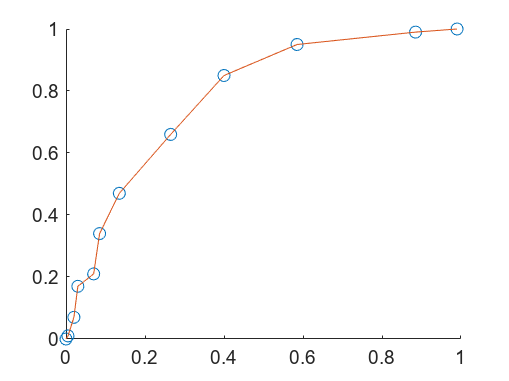

figure 
hold on
scatter(fpr,tpr)
plot(fpr,tpr)
hold off

## c. How would you generate an approximate boxplot for the two categories?

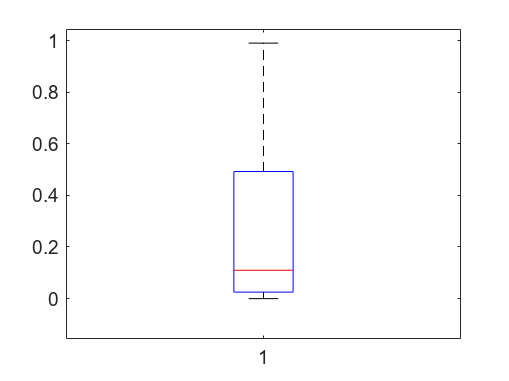

boxplot(fpr)

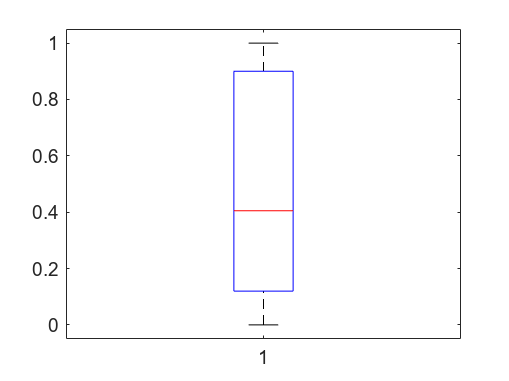

boxplot(tpr)

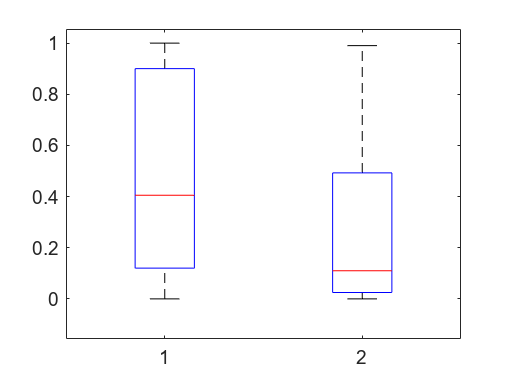

% Correction: 
boxplot([tpr fpr])

## Q3 The code below constructs and displays a training set and test set for a simple 2-D classification task.

## a. Paste the code into Matlab to generate pattern sets train and test.

train.smat=2*rand(30,2)-1

train = struct with fields:
    smat: [30×2 double]

dtrain = sqrt(diag(train.smat*train.smat'));
train.tmat=(dtrain<.85).*(dtrain>.45)

train = struct with fields:
    smat: [30×2 double]
    tmat: [30×1 double]

ktrain=[train.tmat,zeros(30,1),1-train.tmat];
figure
scatter(train.smat(:,1),train.smat(:,2),300,ktrain,'filled')
test.smat=2*rand(20,2)-1

test = struct with fields:
    smat: [20×2 double]

dtest = sqrt(diag(test.smat*test.smat'));
test.tmat=(dtest<.85).*(dtest>.45)

test = struct with fields:
    smat: [20×2 double]
    tmat: [20×1 double]

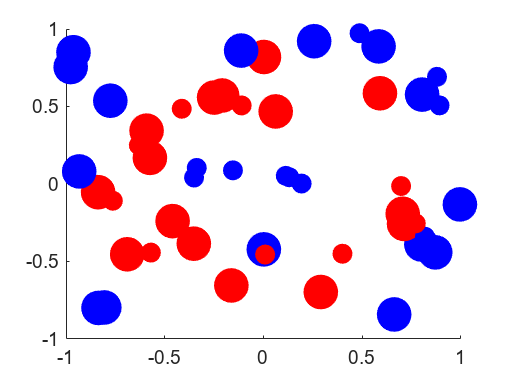

ktest=[test.tmat,zeros(20,1),1-test.tmat];
hold on
scatter(test.smat(:,1),test.smat(:,2),100,ktest,'filled')

## b. Initialize a network with 4 hidden units, and run bp3 for n iterations (where 10000<n<20000) at a learning rate dt (where .02 < dt < .2) using the pattern set train.

% init network
q3net0 = initnet3(2,4,1,2,2,rs);
% train
q3net10k = bp3(q3net0,train,10000,.1,0,rs)

q3net10k = struct with fields:
      wih: [4×2 double]
    hbias: [5.0763 4.2437 1.071 0.14212]
    whout: [4.8261 4.4908 2.9258 -2.2026]
    obias: -6.6174

## c. Use forw3 to test the final network on the test pattern set.

% applying the testing pattern to the trained network
testresult = forw3(q3net10k,test)

testresult = struct with fields:
    stim: [20×2 double]
     hid: [20×4 double]
     out: [20×1 double]

testresult.hid

ans =        0.9678      0.94065       0.6568     -0.14657
      0.88668      0.94368      0.78148     -0.25034
      0.99416      0.96565       0.3755      0.10489
      0.49878      0.73001      0.90904     -0.60684
       0.5237       0.9966      0.82789     0.088296
      0.99478      0.96817      0.35095      0.12808
      0.99993      0.99882     -0.63378      0.79736
      0.99885      0.99902     -0.19388      0.70379
      0.99991      0.99784     -0.57211      0.74539
      0.99967     -0.60296      0.20026     -0.52482


testresult.out

ans =       0.98925
      0.99132
      0.96722
       0.9554
      0.93172
       0.9636
      0.28561
      0.63925
      0.34833
     0.059591


## d. Generate an ROC curve from the responses to the test set.

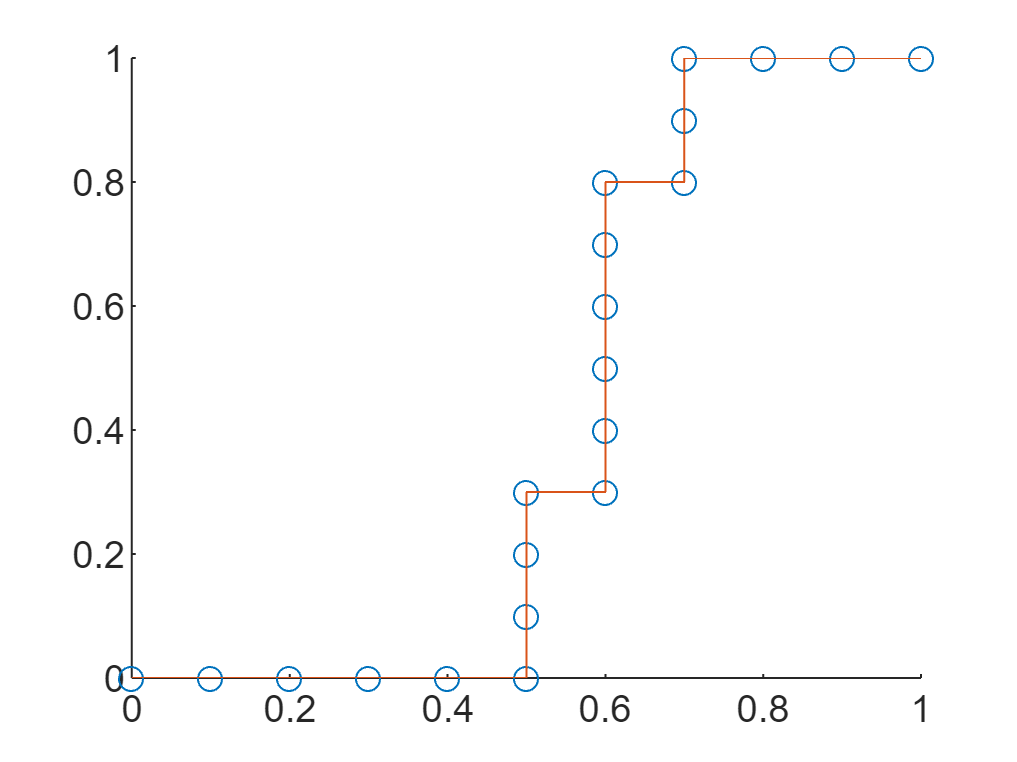

[tpr,fpr,thresholds]=roc(test.tmat', testresult.out');
figure 
hold on
scatter(fpr,tpr)
plot(fpr,tpr)

## Attachements

function [bestnet,finalnet,errmat]=bp3trvats(net0,trlist,valist,tslist,niter,eta,nlev,eps)
netk=net0;
maxiter=niter;
ase=2*eps ; % not use in this function
valbest=10;
i=0 ;
errmat=[] ;
bestnet = netk;
while ((ase>eps)&&(i<maxiter))
    netk=cyc3(netk,trlist,eta,nlev) ; % Training procedure
    
    activ=forw3(netk,trlist) ;
    diff = trlist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    trerr=sse/numel(diff) ; % Training error

    activ=forw3(netk,valist) ;
    diff = valist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    valerr=sse/numel(diff) ; % Validation error
    if (valerr<valbest)
        % Save the network with the lowest validation error
        ibest=i ;
        valbest=valerr;
        bestnet=netk;
    end

    activ=forw3(netk,tslist) ;
    diff = tslist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    tserr=sse/numel(diff) ; % Test error

    errmat=[errmat;[i,trerr,valerr,tserr]];
    i=i+1 ;
end
finalnet=netk;
finalnet.iter=i;
finalnet.err=ase;
bestnet.iter=ibest; % fixed
bestnet.err=valbest; % fixed
end

% Correction: bp3errortrack
function [finalnet,trucurv,testcurv]= bp3errortrack(net0,trset,testset,niter,eta,nlev)
netk=net0;
trucurv=[];
testcurv=[];
for i=1:niter
    netk=cyc3(netk,trset,eta,nlev);
    if (mod(1,100)==0)
        [trerr testerr]=errortraintest(netk,trset,testset);
        trucurv=[trcurv,trerr];
        testcurv=[testcurv,testerr];
    end
end
finalnet=netk;
end
% Correction: errortraintest
function [trerr, tserr] = errortraintest(netk,trlist,tslist)
activ=forw3(netk,trlist) ;
diff = trlist.tmat-activ.out;
sse=sum(sum(diff.*diff));
trerr=sse/numel(diff) ; % Training error

activ=forw3(netk,tslist) ;
diff = tslist.tmat-activ.out;
sse=sum(sum(diff.*diff));
tserr=sse/numel(diff) ; % Test error
end